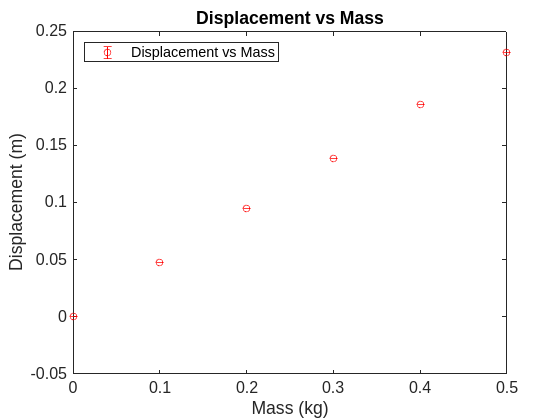

% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% -------------------------------------
% Spring Force vs Displacement Analysis
% -------------------------------------

% Preallocation and setup
num_measurements = 6;
pos_means = zeros(1, num_measurements);
pos_std_deviations = zeros(1, num_measurements);
pos_err_mean = zeros(1, num_measurements);
filename.Temp = "S4L6_%d.txt";

% Loop to import and process data
for i = 1:num_measurements
    % Read data from corresponding file
    data = readtable(sprintf(filename.Temp, i));
    
    % Assign all position data from ith file to current_position
    current_positions = data.Position;
    N = length(current_positions);

    % Find the mean of the position for the current file
    position_mean = mean(current_positions);

    % Store the original mean position
    pos_means(i) = position_mean;

    % Calculate std deviation and std error mean
    pos_std_deviations(i) = std(current_positions);
    pos_err_mean(i) = pos_std_deviations(i) / sqrt(N);
end

% Mass of weights in kg (from stamps on weights)
mass_weights = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5];

% Invert the positions to make show positive displacement
displacements = max(pos_means) - pos_means; 

% -------------------------------
% Plot: Position vs. Mass
% -------------------------------
figure; grid on; box on;

% Plot inverted Position with error bars
errorbar(mass_weights, displacements, pos_err_mean, ...
    'ro', 'MarkerSize', 5, 'DisplayName', 'Displacement vs Mass');

% Title and Labels with Uncertainties
title('Displacement vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);
legend('Location', 'northwest');
set(gca, 'FontSize', 12);